clear
clc
load robotData.mat

% Visualize the given Data
plotSensors(sensor1,label);
plotSensors(sensor2,label);

% Concatenate and transpose data
bothSensor = [sensor1 sensor2]';
labelRow  = label';
summary(labelRow)

     Move-Forward      Sharp-Right-Turn      Slight-Left-Turn      Slight-Right-Turn 
     2205              2097                   328                   826              


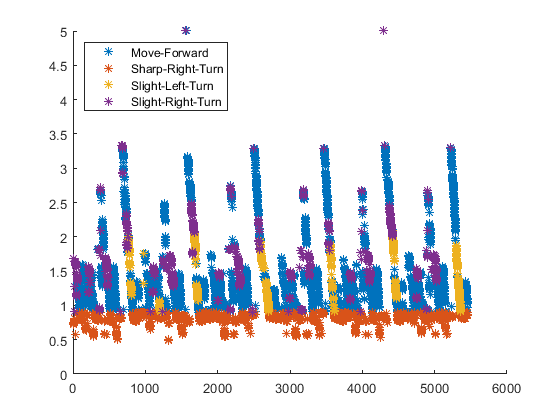

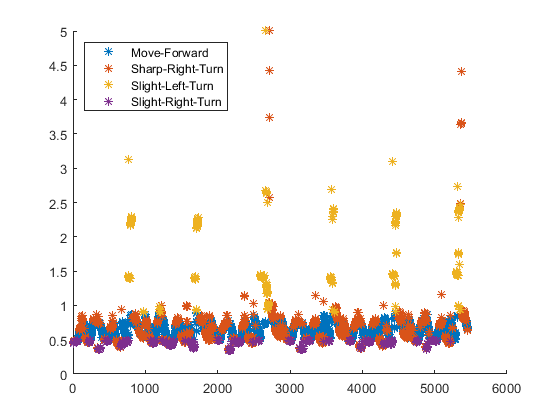

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:11 |       12.21% |       40.80% |       1.3989 |       1.9200 |          0.0100 |


|      50 |          50 |       00:05:10 |       80.06% |       81.40% |       0.4871 |       0.4436 |          0.0100 |


|     100 |         100 |       00:10:08 |       94.64% |       89.40% |       0.1491 |       0.3227 |          0.0100 |


|     150 |         150 |       00:15:09 |       96.61% |       91.60% |       0.0950 |       0.2950 |          0.0100 |


|     200 |         200 |       00:20:08 |       91.86% |       87.00% |       0.2153 |       0.3895 |          0.0100 |


|     250 |         250 |       00:25:07 |       96.97% |       93.00% |       0.0868 |       0.2337 |          0.0100 |


|     300 |         300 |       00:30:07 |       99.09% |       94.20% |       0.0336 |       0.2370 |          0.0100 |


|     350 |         350 |       00:35:09 |       97.65% |       93.20% |       0.0680 |       0.2418 |          0.0100 |


|======================================================================================================================|



% Create training testing and validation sets
n = 1000;
m = 500;

XTrain = bothSensor(:,1:end-(n+m));
YTrain = labelRow(1:end-(n+m));

XValidation = bothSensor(:,end-(n+m)+1:end-n);
YValidation = labelRow(end-(n+m)+1:end-n);

XTest = bothSensor(:,end-n+1:end);
YTest = labelRow(end-n+1:end);


% Create the layers of the Bidirectional LSTM model
bilstmLayer = [
    sequenceInputLayer(2)
    bilstmLayer(100,'Outputmode','sequence')
    bilstmLayer(100,'Outputmode','sequence')
    fullyConnectedLayer(4)
    softmaxLayer()
    classificationLayer()];
%Set the options of the model
options = trainingOptions('adam',...
    'Plots','training-progress',...
    "MaxEpochs",350,...
    'ValidationData',{XValidation,YValidation}, ...
    'Plots','training-progress', ...
    "InitialLearnRate",0.01);
%     'GradientThreshold',1, ...
%     'Shuffle','every-epoch', ...
%     'LearnRateDropPeriod',200,...
%     'LearnRateSchedule','piecewise'

%Train the model
net = trainNetwork(XTrain,YTrain,bilstmLayer,options);


%Evaluate Model
prediction = classify(net,XTest);
accuracy = nnz(prediction == YTest)/numel(YTest)

accuracy = 0.9280

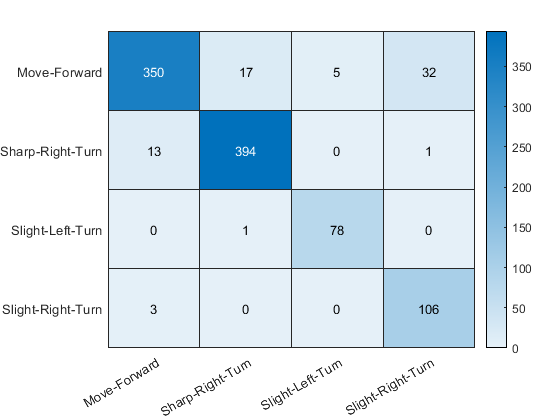


%Train the model and evaluate in a double for loop for different epoch and learning rate
% Set v in format:starting epoch: range of epoch: final epoch
% Set W in format:starting learning rate:range learning rate:final learning rate
%     v = 1:499:500
%     w = 0.001:0.001:0.001
%     testAllModels(v,w,XTrain,YTrain,XTest,YTest,bilstmLayer)


%Visualize the result
[cmap,clabel] = confusionmat(YTest,prediction);
hmap = heatmap(clabel,clabel,cmap);

function testAllModels(v,w,XTrain,YTrain,XTest,YTest,bilstmLayer)
fileID = fopen('Result','w');

    for epoch = v
        for rate = w
            
            %Set the options of the model
            options = trainingOptions('adam','Plots',...
                'training-progress',"MaxEpochs",epoch,"InitialLearnRate",rate);
            
            %Train the model
            net = trainNetwork(XTrain,YTrain,bilstmLayer,options);
            
            %Evaluate Model
            prediction = classify(net,XTest);
            accuracy = nnz(prediction == YTest)/numel(YTest);
            
            %Create a txt document with the accuracy
            accDisp = ['Accuracy_' num2str(epoch,'%.2f')...
                '_' num2str(rate,'%.3f') '.doc'];
            fprintf(fileID, accDisp);
            fprintf(fileID,'%.2f\n',accuracy);
    
        end
    end

fclose(fileID);

end

function plotSensors(X,Y)

    figure
    cat = categories(Y);
    
    for i = 1:length(cat)
        label = cat(i);
        idx = find(Y == label);
        hold on
        plot(idx,X(idx),'*')
    end
    
    hold off
    legend(cat,'Location','northwest')
    
end
